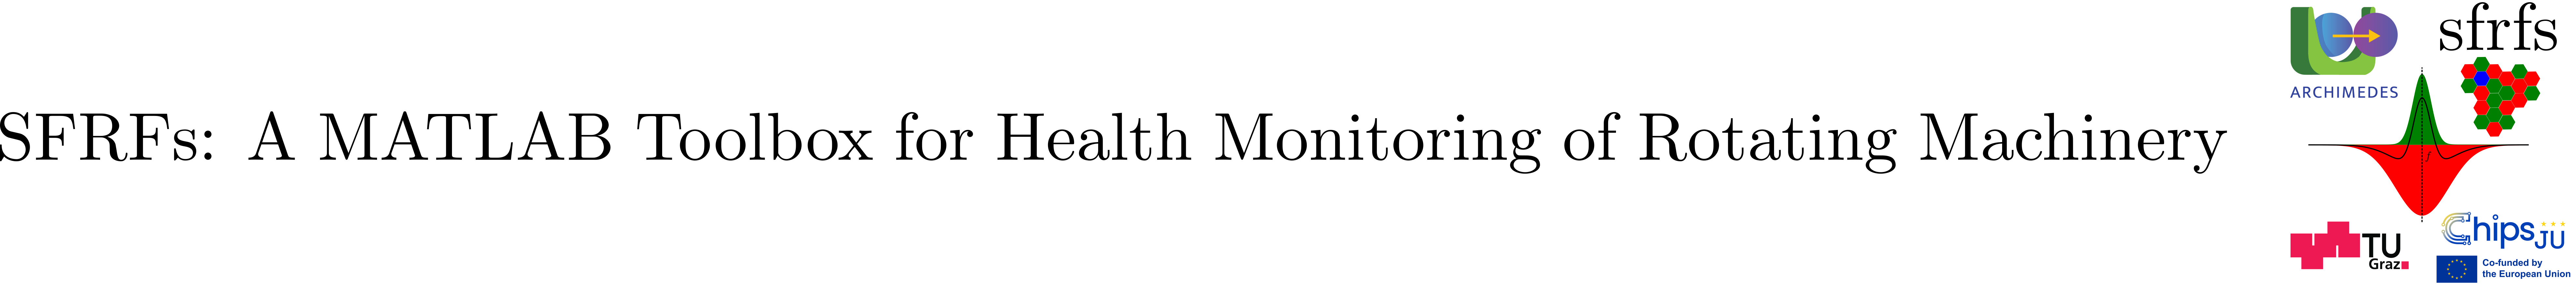

# ContrastPolarityFilter

## Summary

`ContrastPolarityFilter` is a static utility class that resolves harmonic-indexed contrast responses from two sensors using polarity agreement and a quantile-based agreement floor with asymmetric temporal smoothing.

**Key features:**

- Computes shared contrast magnitudes and signed polarity agreement between two sensors.

- Estimates a nonnegative agreement floor from a configurable quantile of signed agreement strengths.

- Updates the agreement floor using independent rise and fall coefficients.

- Retains harmonics exhibiting concordant polarities and sufficient shared contrast magnitude.

- Computes resolved contrast as the arithmetic mean of retained sensor-local contrasts.

- Returns retained harmonic indices, updated agreement-floor history, resolved contrasts, and shared magnitudes.

- Maintains temporal state explicitly without storing internal object state.

The class implements the cross-sensor contrast polarity filtering mechanism used for bearing degradation monitoring, as presented in [3].

## Description

`ContrastPolarityFilter` provides the static method `apply` for resolving contrast responses from two sensors over a common set of harmonic indices.

For each harmonic, the method computes the minimum absolute contrast magnitude and the product of the two contrast signs. Their product defines a signed agreement strength, which is used to estimate a nonnegative agreement floor from a configurable quantile across the harmonic population.

The agreement floor evolves over successive observations through asymmetric exponential smoothing. Independent rise and fall coefficients control its response to increasing and decreasing instantaneous agreement thresholds. The first observation initializes the floor directly from the estimated quantile.

A harmonic is retained when its sensor-local contrasts have matching nonzero signs and its shared magnitude is greater than or equal to the current agreement floor. Its resolved contrast is the arithmetic mean of the two sensor-local contrasts; all other harmonics receive zero.

The method returns the retained harmonic indices, updated agreement-floor history, resolved contrast vector, and shared magnitude vector. Temporal state is supplied and returned explicitly, enabling sequential processing without internal state.

The class operates on contrast responses rather than raw spectra or receptive-field gain functions. It can therefore be used downstream of `LiftedHarmonicResponseCompute` and `ContrastMappings` without depending directly on either class.

**See also:** [`LiftedHarmonicResponseCompute`](matlab:open('./LiftedHarmonicResponseCompute.mlx')), [`ContrastMappings`](matlab:open('./ContrastMappings.mlx')), [`ReceptiveFieldResponseFunctions`](matlab:open('./ReceptiveFieldResponseFunctions.mlx')).

## Public methods

apply

Resolves harmonic-indexed contrast responses from two sensors using signed polarity agreement and a temporally updated agreement floor.

For each harmonic, the method computes the shared contrast magnitude and polarity agreement. A nonnegative threshold is estimated from a specified quantile of signed agreement strengths and updated using asymmetric rise and fall coefficients.

Harmonics exhibiting matching nonzero polarities and shared magnitude greater than or equal to the updated agreement floor are retained. Their resolved contrast is the arithmetic mean of the sensor-local contrasts; other harmonics receive zero.

**Syntax**

`[Hrel, tau, c, s] = ContrastPolarityFilter.apply( ...`

`    cV, cH, t, tau, q, alphaUp, alphaDown);`

**Parameters**

The contrast arrays must contain finite real numeric values. The agreement-floor history must be nonempty, finite, and nonnegative.

At `t = 1`, the agreement floor is initialized directly from the estimated quantile. For subsequent observations, the corresponding rise or fall coefficient determines the update.

**Output**

For each harmonic (h), the shared magnitude $s_h$ and polarity agreement $p_h$ are defined as


$$s_h = \min(|c_{V,h}|,|c_{H,h}|)$$



$$p_h = \mathrm{sign}(c_{V,h})\,\mathrm{sign}(c_{H,h})$$


The instantaneous agreement floor at time t, $\widehat{\tau}_t $, is given by


$$r_h = p_h s_h$$



$$\widehat{\tau}_t = \max(0,Q_q(r_1,\ldots,r_H))$$


The temporal agreement floor is initialized by ($\tau_1=\widehat{\tau}_1$) and, for (t>1), updated according to


$$\tau_t = \tau_{t-1}
+ \alpha_{\mathrm{Up}}\max(\widehat{\tau}_t-\tau_{t-1},0)
+ \alpha_{\mathrm{Down}}\min(\widehat{\tau}_t-\tau_{t-1},0)$$


The resolved contrast is


$$c_h = \frac{1}{2}(c_{V,h}+c_{H,h})\,
\mathbf{1}_{\{p_h=1,\ s_h\geq\tau_t\}}$$


The method does not maintain internal temporal state. Successive observations must pass the updated `tau` returned by the preceding invocation.

## Example

This example illustrates cross-sensor harmonic contrast polarity agreement and asymmetric temporal filtering. We construct deterministic synthetic contrast sequences for two sensors, comprising eight harmonics and 60 observations.

The experiment considers three successive regimes: weak agreement, strong agreement, and declining agreement. Some harmonics exhibit concordant positive or negative polarities, while others exhibit disagreement between sensors.

### Synthetic harmonic contrast sequences

The contrast sequences are specified directly because `ContrastPolarityFilter` operates downstream of receptive-field response computation and contrast mapping.


% Configure the synthetic experiment
nObservations = 60;
nHarmonics = 8;


% Quantile level for estimating the instantaneous agreement floor
q = 0.75;

% Rise coefficient: faster adaptation to increasing agreement strength
alphaUp = 1/4;

% Fall coefficient: slower adaptation to decreasing agreement strength
alphaDown = 1/12;


% Harmonic contrasts in three successive regimes
baseContrast = [ ...
    1.0, -0.8,  0.6, -0.5,  0.4, -0.3,  0.2, -0.1];

regimeStrength = [ ...
    0.5 * ones(20, 1); ...
    3.0 * ones(20, 1); ...
    0.5 * ones(20, 1)];

C1 = regimeStrength * baseContrast;
C2 = C1;

% Introduce disagreement at selected harmonics
C2(:, [4, 7]) = -C2(:, [4, 7]);

% Introduce additional disagreement during the final regime
C2(41:end, 5) = -C2(41:end, 5);


### Cross-sensor contrast polarity filtering

We process the observations sequentially. At each step, the filter estimates the instantaneous agreement threshold, updates the temporal agreement floor, and resolves the harmonic contrasts.

The agreement-floor history is passed explicitly between successive calls.

% Allocate outputs
tau = zeros(nObservations, 1);
resolvedContrast = zeros(nObservations, nHarmonics);
sharedMagnitude = zeros(nObservations, nHarmonics);
instantaneousThreshold = zeros(nObservations, 1);

% Apply the filter sequentially
for t = 1:nObservations

    [~, tau, resolvedContrast(t, :), sharedMagnitude(t, :)] = ...
        ContrastPolarityFilter.apply( ...
        C1(t, :), C2(t, :), ...
        t, tau, q, alphaUp, alphaDown);

    signedStrength = ...
        sign(C1(t, :)) .* sign(C2(t, :)) ...
        .* sharedMagnitude(t, :);

    instantaneousThreshold(t) = ...
        max(0, quantile(signedStrength, q));
end

### Visualizing the agreement floor and resolved contrast

The upper panels display the sensor-local contrast inputs using a common symmetric color scale. The lower-left panel compares the instantaneous agreement threshold with its asymmetrically smoothed history, while the lower-right panel displays the resolved harmonic contrasts.

The experiment is designed to reveal the faster rise and slower decline of the agreement floor, while distinguishing retained positive and negative contrasts from rejected harmonic components.

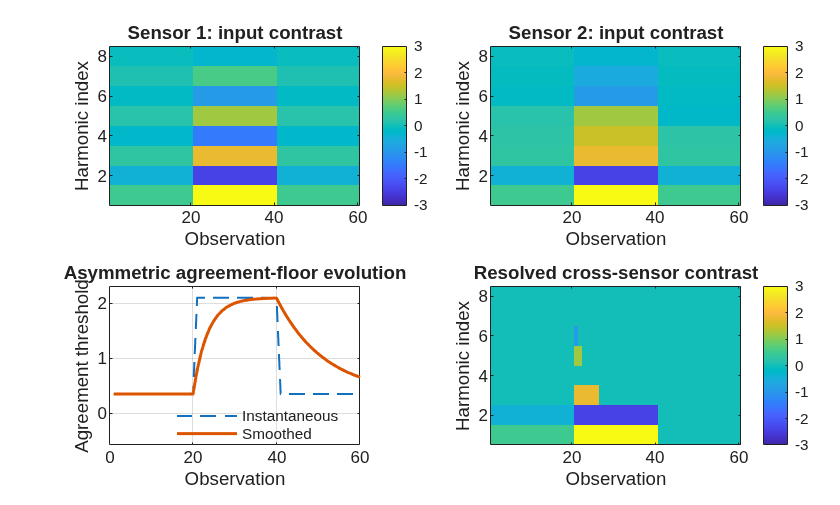


figure;
tiledlayout(2, 2, TileSpacing="compact");

% Use a common symmetric scale for all contrast maps
cMax = max(abs([C1(:); C2(:); resolvedContrast(:)]));

% First sensor: input contrast
nexttile;
imagesc(C1.');
clim([-cMax, cMax]);
colorbar;
title('Sensor 1: input contrast');
xlabel('Observation');
ylabel('Harmonic index');
set(gca, YDir='normal');

% Second sensor: input contrast
nexttile;
imagesc(C2.');
clim([-cMax, cMax]);
colorbar;
title('Sensor 2: input contrast');
xlabel('Observation');
ylabel('Harmonic index');
set(gca, YDir='normal');


% Temporal agreement floor
ax = nexttile;

plot(ax, 1:nObservations, instantaneousThreshold, ...
    '--', LineWidth=1);
hold(ax, 'on');
plot(ax, 1:nObservations, tau, ...
    '-', LineWidth=1.5);
hold(ax, 'off');

grid(ax, 'on');
xlabel(ax, 'Observation');
ylabel(ax, 'Agreement threshold');
title(ax, 'Asymmetric agreement-floor evolution');

% Reserve space below zero for the legend
yMax = 1.1 * max([instantaneousThreshold; tau]);
ylim(ax, [-0.25*yMax, yMax]);


lgd = legend(ax, {'Instantaneous', 'Smoothed'}, ...
    Orientation='vertical', ...
    Box='off');

% Move the legend further down within the reserved region
lgd.Units = 'normalized';
lgd.Position(2) = 0.12;



% Resolved cross-sensor contrast
nexttile;
imagesc(resolvedContrast.');
clim([-cMax, cMax]);
colorbar;
title('Resolved cross-sensor contrast');
xlabel('Observation');
ylabel('Harmonic index');
set(gca, YDir='normal');

## API documentation

### MATLAB help

The MATLAB `help` command displays the class documentation extracted from its source file.

help ContrastPolarityFilter

 ContrastPolarityFilter Cross-sensor contrast polarity agreement filter.
 
  Resolves harmonic contrast from two sensors using signed polarity
  agreement and a quantile-based agreement floor with asymmetric
  temporal smoothing.
 
  The static apply method returns retained harmonic indices, the
  updated floor history, resolved contrast, and shared magnitudes.
 
  Reference:
  Muñoz Gutiérrez, S., and Wotawa, F. (2026).
  Spectral Contrast Polarity Analysis and Adaptive Sensor Fusion
  for Bearing Degradation Monitoring.
  In Proceedings of the 2026 IEEE International Conference on
  Dependable Systems and Applications (DSA 2026). IEEE.
  (To appear.)

    Documentation for ContrastPolarityFilter



### MATLAB documentation

The MATLAB `doc` command opens the corresponding documentation in the MATLAB Help Browser.

doc ContrastPolarityFilter

## Source code

The source code of this class can be found in [`ContrastPolarityFilter`](matlab:open('./ContrastPolarityFilter.mlx')).

edit ContrastPolarityFilter

## Test

Unit testing for the class is implemented in [`TestContrastPolarityFilter`](matlab:open('../../../tests/TestContrastPolarityFilter.m')).

res = runtests('tests/TestContrastPolarityFilter.m');

Setting up ProjectFixture
Done setting up ProjectFixture: Project 'sfrfs-toolbox' is already loaded. Setup is not required.
__________

Running TestContrastPolarityFilter
.........
Done TestContrastPolarityFilter
__________

Tearing down ProjectFixture
Done tearing down ProjectFixture: Teardown is not required.
__________



SFRFsTestUtil.printTestSummary(res, 80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestContrastPolarityFilter/basicAgreementSelection                               | Passed
TestContrastPolarityFilter/quantileUsesSignedEvidencePopulation                  | Passed
TestContrastPolarityFilter/floorClampedToZero                                    | Passed
TestContrastPolarityFilter/risingFloorUsesRiseRate                               | Passed
TestContrastPolarityFilter/fallingFloorUsesFallRate                              | Passed
TestContrastPolarityFilter/disagreementIsRejected                                | Passed
TestContrastPolarityFilter/mismatchedSizesFail                                   | Passed
TestContrastPolarityFilter/nonFiniteInputsFail                                   | Passed
TestContrastPolarityFilter/invalidFloorFails                                     | Passed



## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](https://doi.org/10.5281/zenodo.17631784?utm_source=chatgpt.com).

## **References**

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1–9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025). DOI: [10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9?utm_source=chatgpt.com).

- [2] Stan Muñoz Gutiérrez and Franz Wotawa. A Formal Framework for Spectral Fault Receptive Fields (with Examples for Bearing Health Monitoring). Technical Report TR-SFRFs-v1.0.1, Institute of Software Engineering and Artificial Intelligence, Graz University of Technology, Graz, Austria (2026).

- [3] Stan Muñoz Gutiérrez and Franz Wotawa. Spectral Contrast Polarity Analysis and Adaptive Sensor Fusion for Bearing Degradation Monitoring. In Proceedings of the 2026 IEEE International Conference on Dependable Systems and Applications (DSA 2026). IEEE. (To appear; bibliographic details provisional.)